## **Visualisation des différentes configurations du robot pour suivre une trajectoire**

Ce code permet, après definition des variables, des longueurs des bras du robot, de la position desiree de l'effecteur, du nombre de solution souhaités affichées, et des butées de chaque articulation, de générer l'espace de travail du robot, puis de le visualiser dans les configurations possibles pour atteindre le point désiré par résolution de la cinmeatique inverse par la méthode variationnelle. 

### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail

Cette partie procède tout d'abord à une verification de l'appartenance du point désiré de l'effecteur à l'esapce de travail du robot. Si cela est vérifé on lance alors le calcul de cinématique inverse par la méthode variationnelle. 

Puis on affiche les solutions , d'abord en raidan et ensuite en degrès.

### Définition des variables 

disp('Butées de chaque theta:')

Butées de chaque theta:


% Chargement de la matrice butee à partir du fichier .mat
load('butee.mat'); % Charge la matrice butee à partir du fichier butee.mat
disp(butee);

   -90    90
   -95    95
   -90    90
   -90    90
   -90    90



load('solutionsfiltreepoint1.mat')
disp(solutions_point1)

    1.0000   64.3763  -59.6601   -3.6226  -15.3881  -38.5657    9.0000    0.0000
    1.0000  -32.4058    2.1540   67.4513  -44.8419   62.7285    9.0000    0.0000
    1.0000  -52.7386   28.4118   44.7176   -3.4112   33.6758    9.0000   -0.0000
    1.0000  -21.5791   54.4242    4.6433  -49.7384  -45.1227    9.0000    0.0000
    1.0000   63.1611  -62.0309   -0.3896   -6.6162  -50.4726    9.0000   -0.0000
    1.0000  -14.4770   52.0869   -3.7950  -59.2220  -27.0501    9.0000    0.0000
    1.0000  -35.8809   59.6679  -45.3753   -8.6235   88.6672    9.0000   -0.0000
    1.0000  -28.2520   39.4127   37.4665  -32.2287  -74.5809    9.0000    0.0000




% Convertir les angles de degrés à radians
solutions_point1_angles_radians = deg2rad(solutions_point1(:, 2:6));

% Ramener les angles dans l'intervalle [0, 2*pi]
solutions_point1_angles_radians = mod(solutions_point1_angles_radians, 2*pi);

% Afficher les angles en radians dans l'intervalle [0, 2*pi]
disp('Angles en radians pour le point 1 de la trajectoire (intervalle [0, 2*pi]) :');

Angles en radians pour le point 1 de la trajectoire (intervalle [0, 2*pi]) :


disp(solutions_point1_angles_radians);

    1.1236    5.2419    6.2200    6.0146    5.6101
    5.7176    0.0376    1.1772    5.5005    1.0948
    5.3627    0.4959    0.7805    6.2236    0.5878
    5.9066    0.9499    0.0810    5.4151    5.4956
    1.1024    5.2005    6.2764    6.1677    5.4023
    6.0305    0.9091    6.2170    5.2496    5.8111
    5.6569    1.0414    5.4912    6.1327    1.5475
    5.7901    0.6879    0.6539    5.7207    4.9815





% Initialiser une matrice pour stocker les résultats finaux
final_results = [];

% Paramètres pour d'ajustement du rayon
max_iterations = 1;
tolerance = 1;
% Vecteur pour stocker les rayons actualisés

### Resolution IK pour chaque points de la trajectoire après avoir vérifié si elle appartient à l'espace de travail

% Créer une nouvelle figure à l'extérieur de la boucle
figure;

% Initialiser la matrice finale en dehors de la boucle
final_results_all = [];

% Boucle sur chaque ligne de point1_solutions
for row = 1:size(solutions_point1_angles_radians, 1)  
    % Modifier theta_init avec les valeurs de la ligne actuelle de point1_solutions
    theta_init = solutions_point1_angles_radians(row, :);

    % Réinitialiser les valeurs initiales des angles précédents avec theta_init
    theta_prev = theta_init;

    % Initialiser la matrice finale pour chaque configuration initiale
    final_results = [];

    % Itérer sur chaque point de la trajectoire
    for i = 1:num_points       
        % Utiliser les solutions précédentes comme points de départ pour les angles
        if i > 1
            % Pour les points suivants, utiliser les angles de la dernière solution
            theta_prev = final_results(final_results(:, 1) == i-1, 2:end);
        end

        % Initialiser le rayon avec le rayon d'origine
        current_radius = radius;

        % Calculer les coordonnées du point de la trajectoire avec le rayon actuel
        x_desired = current_radius * cos(theta_traj(i));
        y_desired = current_radius * sin(theta_traj(i));

        % Appeler la fonction de cinématique inverse pour trouver les solutions pour ce point
        num_configurations=1;
        all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev);

        % Ajouter une colonne pour le numéro du point de trajectoire
        point_numbers = repmat(i, size(all_solutions, 1), 1);
        all_solutions_with_point_numbers = [point_numbers, all_solutions];

        % Ajouter les résultats à la matrice finale pour cette configuration initiale
        final_results = [final_results; all_solutions_with_point_numbers];

        % Réinitialiser theta_prev avec les angles trouvés pour ce point
        theta_prev = all_solutions(end, 2:end);

    end
    
    % Ajouter les résultats de cette configuration initiale à la matrice finale globale
    final_results_all = [final_results_all; final_results];
end

### Affichage des résultats de cinématique inverse

% Initialiser une colonne de numéros de configuration initiale
CI_numbers = (1:size(solutions_point1_angles_radians, 1)).';

% Répéter chaque numéro de configuration initiale pour chaque point de la trajectoire
CI_numbers_repeated = repelem(CI_numbers, num_points);

% Ajouter la colonne CI_numbers à gauche de la matrice finale
final_results_all_with_CI = [CI_numbers_repeated, final_results_all];

% Affichage des résultats globaux dans un tableau
fprintf('Résultats Globaux:\n');

Résultats Globaux:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(final_results_all_with_CI);

    1.0000    1.0000    1.1236    5.2419    6.2200    6.0146    5.6101    9.0000    0.0000
    1.0000    2.0000    1.2049    5.3238    6.1962    5.9112    5.6901    8.9391    1.0448
    1.0000    3.0000    1.2992    5.3657    6.2030    5.8318    5.7484    8.7574    2.0755
    1.0000    4.0000    1.4030    5.3772    6.2440    5.7494    5.8024    8.4572    3.0782
    1.0000    5.0000    1.4032    4.9740    1.1066    5.0808    6.2475    8.0427    4.0392
    1.0000    6.0000    1.4633    5.0690    1.1169    4.9657    0.0323    7.5194    4.9456
    1.0000    7.0000    1.5734    5.1270    1.0522    4.9179    0.0832    6.8944    5.7851
    1.0000    8.0000    1.7113    5.1688    0.9329    4.9111    0.1301    6.1762    6.5464
    1.0000    9.0000    1.8591    5.2129    0.7710    4.9326    0.1793    5.3744    7.2191
    1.0000   10.0000    0.4883    0.3648    1.1174    6.0361    4.9588    4.5000    7.7942
    2.0000    1.0000    5.7176    0.0376    1.1772    5.5005    1.0948    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------



save('finalresCI.mat', 'final_results_all_with_CI');

### Visualisation du robot

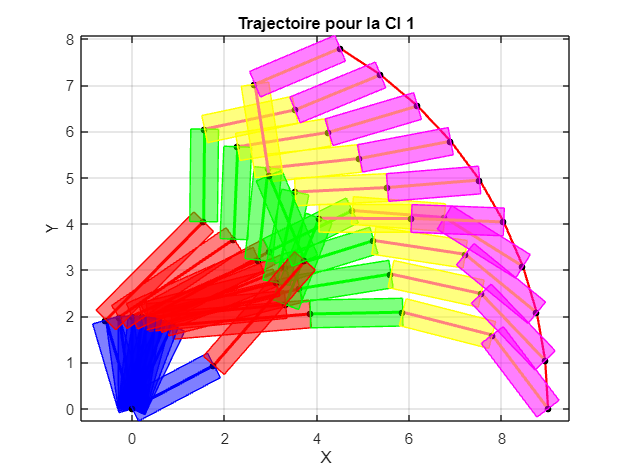

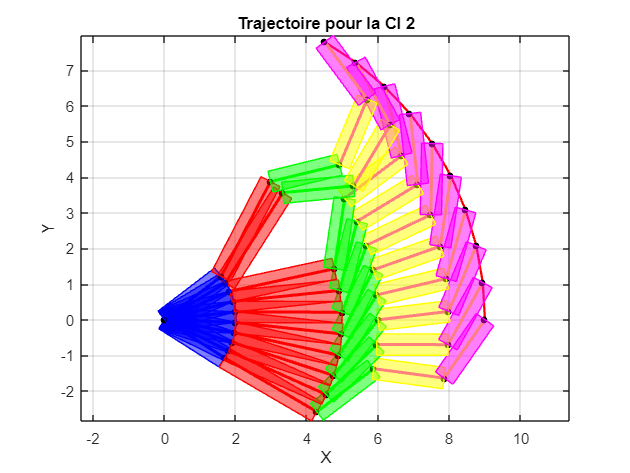

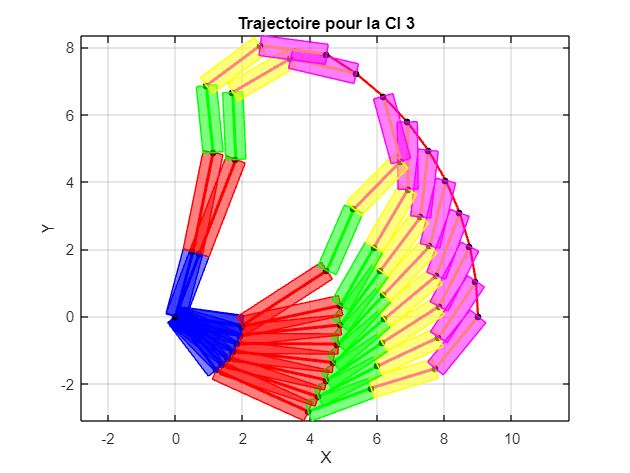

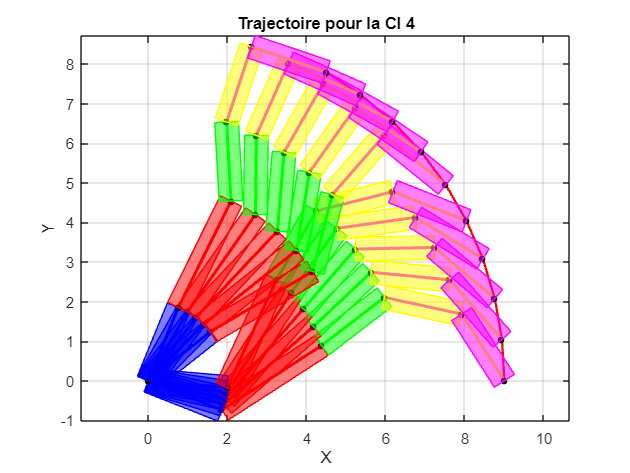

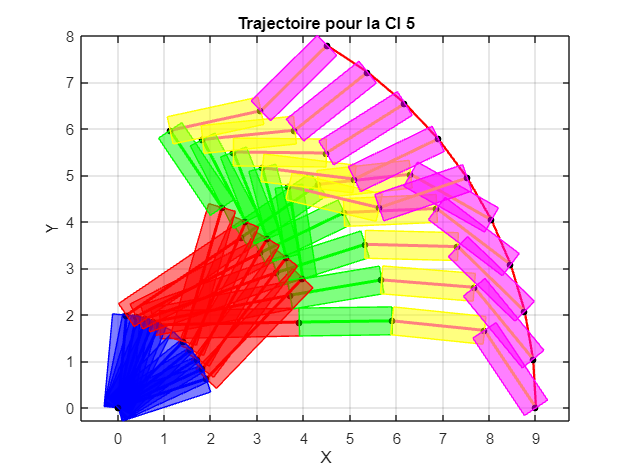

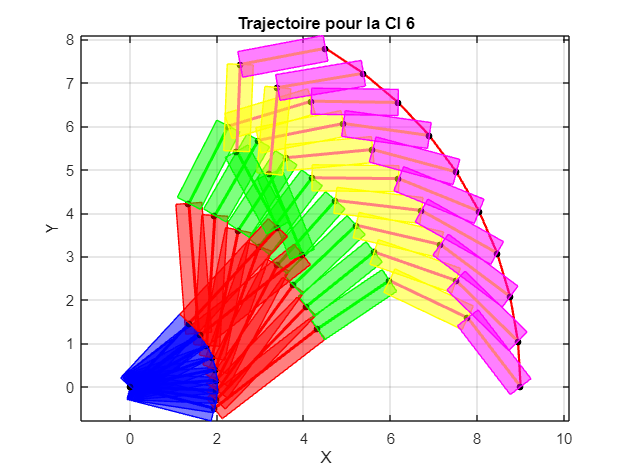

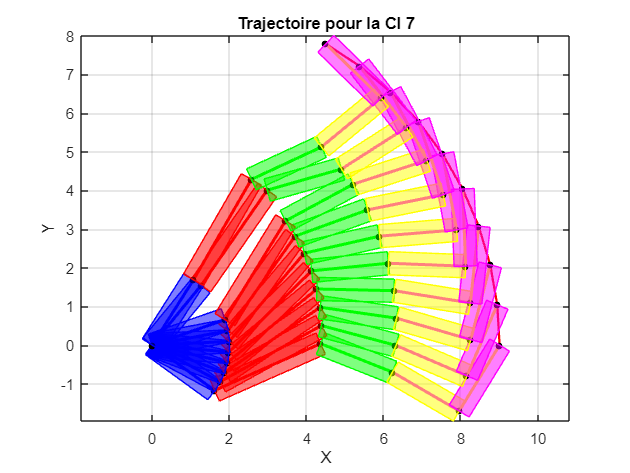

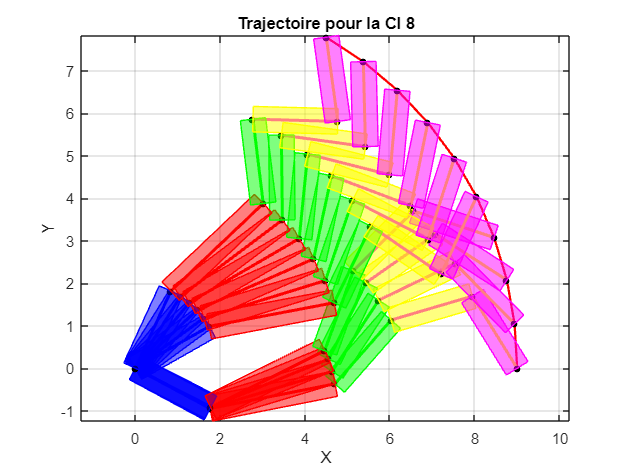

% Pour chaque configuration initiale
for ci = 1:max(CI_numbers)
    % Extraire les indices correspondant à cette configuration initiale
    indices = final_results_all_with_CI(:, 1) == ci;
    
    % Extraire les données pour cette configuration initiale
    data_for_ci = final_results_all_with_CI(indices, :);
    
    % Afficher la trajectoire
    figure;
    plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
    axis equal; % Pour que l'échelle des axes soit égale
    xlabel('X');
    ylabel('Y');
    title(['Trajectoire pour la CI ', num2str(ci)]);
    grid on;
    hold on;
    
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)
        % Extraire les angles d'articulation pour ce point de la trajectoire
        theta1 = data_for_ci(i, 3);
        theta2 = data_for_ci(i, 4);
        theta3 = data_for_ci(i, 5);
        theta4 = data_for_ci(i, 6);
        theta5 = data_for_ci(i, 7);

        % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
        O = [0, 0]; % Position de l'origine
        A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
        B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
        C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
        D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
        E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

        % Tracer le robot pour ce point de la trajectoire
        plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'HandleVisibility', 'off'); % Segment OA
        plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'HandleVisibility', 'off'); % Segment AB
        plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'HandleVisibility', 'off'); % Segment BC
        plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'HandleVisibility', 'off'); % Segment CD
        plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'HandleVisibility', 'off'); % Segment DE
        scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
        % Ajouter des rectangles autour des segments
        rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
        drawSegmentRectangle(O, A, rectWidth, 'b');
        drawSegmentRectangle(A, B, rectWidth, 'r');
        drawSegmentRectangle(B, C, rectWidth, 'g');
        drawSegmentRectangle(C, D, rectWidth, 'y');
        drawSegmentRectangle(D, E, rectWidth, 'm');
        % Mettre en pause pour une durée appropriée
        pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
    end
end

### Variations de chaque angle pour chaque solution

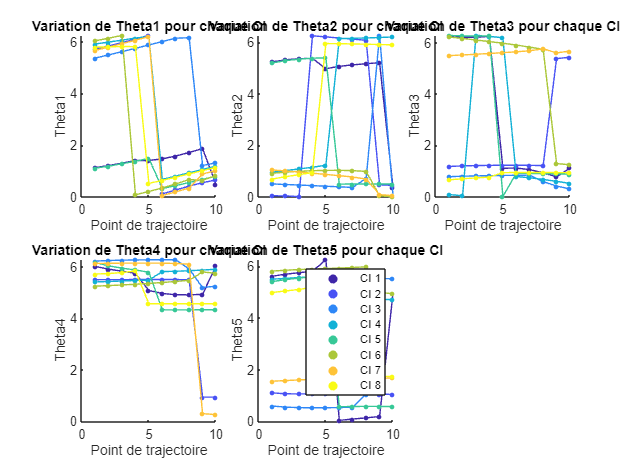


% Affichage des variations de chaque angle pour chaque solution
figure;
% Initialiser un tableau pour stocker les couleurs uniques
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

% Choisir une carte de couleurs
custom_colormap = parula(size(solutions_point1_angles_radians, 1));
%carte de couleurs basée sur la taille de la matrice point1_solutions. Chaque ligne de point1_solutions représente une 
% configuration initiale, et une couleur différente sera utilisée pour chaque configuration.

for joint = 1:5
     % Créer un subplot pour chaque angle d'articulation
    subplot(2, 3, joint);
    
    % Titre de subplot
    title(['Variation de Theta', num2str(joint), ' pour chaque CI']);
    xlabel('Point de trajectoire');
    ylabel(['Theta', num2str(joint)]);
    hold on;
    % Extraire les données pour cet angle (colonne joint+2 car la première colonne est le numéro du point de trajectoire)
    data_for_joint = final_results_all_with_CI(:, joint+2);
    
       % Récupérer les couleurs uniques
    unique_colors = unique(final_results_all_with_CI(:, 1));
    % Parcourir les couleurs et les étiqueter dans la légende
    for i = 1:length(unique_colors)
        scatter(NaN, NaN, 10, custom_colormap(i, :), 'filled', 'DisplayName', ['CI ', num2str(unique_colors(i))]);
    end
    % Regrouper les indices des points par CI
    grouped_indices = {};
    for i = 1:length(unique_colors)
        indices = find(final_results_all_with_CI(:, 1) == unique_colors(i));
        grouped_indices{i} = indices;
    end


   % Tracer une ligne reliant les points de chaque CI avec interpolation linéaire
    for i = 1:length(grouped_indices)
        indices = grouped_indices{i};
        sorted_data = sortrows([final_results_all_with_CI(indices, 2), data_for_joint(indices)]);
        
        % Tracer les points
        scatter(sorted_data(:, 1), sorted_data(:, 2), 10, custom_colormap(i, :), 'filled', 'HandleVisibility', 'off');
        
        % Tracer la courbe d'interpolation linéaire
        x = sorted_data(:, 1);
        y = sorted_data(:, 2);
        interpolated_y = interp1(x, y, x, 'linear');
        plot(x, interpolated_y, '-', 'Color', custom_colormap(i, :), 'LineWidth', .5, 'HandleVisibility', 'off');
    end

end

% Ajouter une légende indiquant à quelle CI chaque couleur correspond
legend('show');

function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev)

    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];
    
     % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        
        
        % Initialiser les angles d'articulation avec les valeurs précédentes
        theta1 = theta_prev(1);
        theta2 = theta_prev(2);
        theta3 = theta_prev(3);
        theta4 = theta_prev(4);
        theta5 = theta_prev(5);

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))));

            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
                 dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Mettre à jour les angles d'articulation précédents pour le prochain point de trajectoire
            theta_prev = [theta1, theta2, theta3, theta4, theta5];
            
            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
end
